# Laboratorio di Automatica (prova del 28 Agosto 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

August 28, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri il sistema di controllo di velocità di un motore elettrico in corrente continua mostrato in Fig. 1, dove 


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{T_m s  + 1}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


è la funzione di trasferimento del motore, da ingresso in tensione $u$ $[V]$ ad uscita in velocità $y$ $[\mathrm{rad/s}]$, mentre


$$C(s)\,=\,\frac{U(s)}{E(s)}\,=\,\frac{k}{s} \left(\frac{1+\tau\,s}{1+\alpha\,\tau\,s}\right)\qquad\quad\text{con}\qquad\quad \alpha=0.17\,,\qquad\tau=0.015$$
  

è la funzione di trasferimento del controllore di velocità, con ingresso l'errore di velocità $e\,[\mathrm{rad/s}]$ ed uscita la tensione di comando $u\,[\mathrm{V}]$.

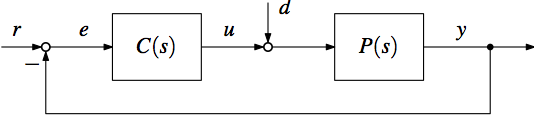

**Figura 1**: Sistema di controllo a retroazione unitaria dall'uscita.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Supponendo $k=1$, tracciare il diagramma di Bode della funzione di trasferimento d'anello $L(s)=P(s)C(s)$, e determinare poi la pulsazione di attraversamento $\omega_{gc}$ e il margine di fase $\varphi_m$.

*Soluzione*.

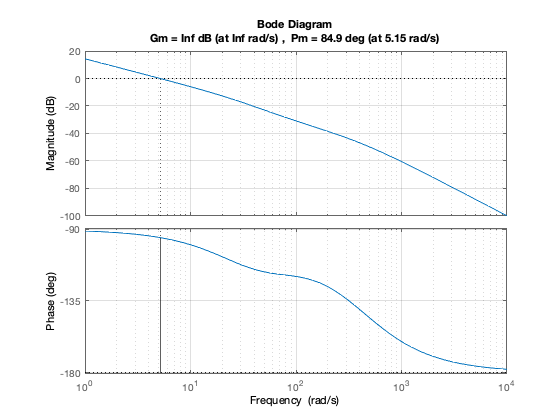

%  define plant tf
Tm = 0.03;
km = 5.2;
sysP = tf(km, [Tm, 1]);

%  define controller tf
a = 0.17;
tau = 0.015;
k = 1;
sysC = tf(1, [1,0]) * tf([tau, 1], [a*tau, 1]);

%  loop tf
sysL = sysP*sysC;

%  loop tf - Bode plot
figure;
margin(sysL);
grid on;

La pulsazione di attraversamento è pari a $\omega_{gc} = 5.15\,\mathrm{rad/s}$, mentre il margine di fase vale $\varphi_m = 84.9\,\mathrm{deg}$.

2) Supponendo $k=1$, calcolare la funzione di trasferimento $T(s)$ del sistema in catena chiusa, dal riferimento $r$all'uscita $y$. Valutare successivamente la risposta$y$ del sistema in catena chiusa ad un segnale di riferimento di velocità $r$ a gradino di ampiezza pari a $300\,\mathrm{rpm}$ (rotations-per-minute, ovvero giri-al-minuto) applicato all'istante $t=0$, e il relativo tempo di salita.

*Nota*: dato che la velocità$y$ è espressa in $[\mathrm{rad/s}]$, si converta il segnale di riferimento $r$ a tale unità di misura, prima di procedere al tracciamento della risposta al gradino.

*Soluzione*.

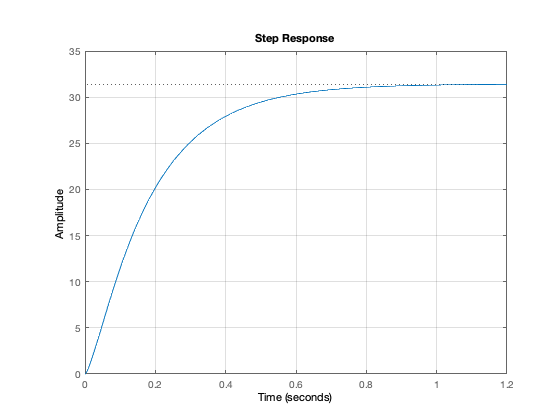

%  closed-loop tf
sysT = feedback(sysL, 1);

%  speed set-point
wm_ref_rpm = 300;                       %  [rpm]
wm_ref_rads = wm_ref_rpm * (2*pi/60);   %  [rad/s]

%  closed-loop step response
figure;
step( sysT * wm_ref_rads );
grid on;


%    get step response params
stepinfo( sysT * wm_ref_rads )

ans = struct with fields:
        RiseTime: 0.3867
    SettlingTime: 0.6941
     SettlingMin: 28.2915
     SettlingMax: 31.3885
       Overshoot: 0
      Undershoot: 0
            Peak: 31.3885
        PeakTime: 1.2305


Il tempo di salita è pari a $t_r = 0.3867\,\mathrm{s}$.

3) Al fine di velocizzare la risposta al gradino del sistema, calcolare il guadagno $k'$ del controllore necessario per portare la pulsazione di attraversamento ad un valore pari a $\omega_{gc}' = (2\pi\times 25)\,\mathrm{rad/s}$ (pari a $25\,\mathrm{Hz}$).

Determinare successivamente il margine di fase $\varphi_m'$ raggiunto dal sistema con tale valore di guadagno.

*Soluzione*.

E' immediato verificare che il nuovo valore di guadagno del controllore è pari a $k'=|L(j\omega_{gc}')|^{-1}$:

%  desired gain-crossover freq
wgc1 = 2*pi*25;

%  loop-tf gain at desired gain-crossover freq
[magL, ~] = bode(sysL, wgc1);

%  controller gain for desired gain-crossover freq
k1 = 1/magL

k1 = 61.2433

Con tale valore di guadagno, il diagramma di Bode della funzione di trasferimento d'anello diventa:

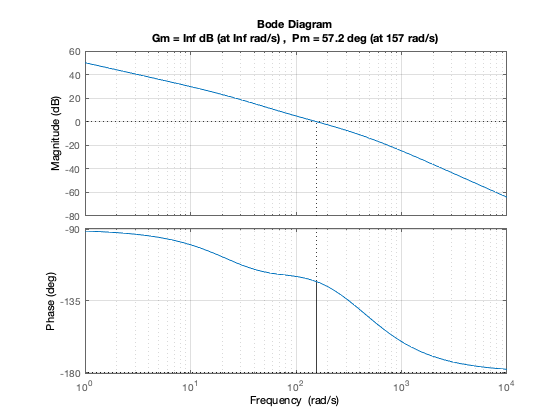

%  new controller tf
sysC1 = k1 * sysC;

%  new loop-tf
sysL1 = sysP*sysC1;

%  new loop-tf - Bode plot
figure;
margin(sysL1);
grid on;

Il nuovo margine di fase è pari a $\varphi_m' = 57\,\mathrm{deg}$.

4) Ripetere il punto 2, utilizzando il valore di guadagno $k'$ ottenuto al punto 3.

*Soluzione*.

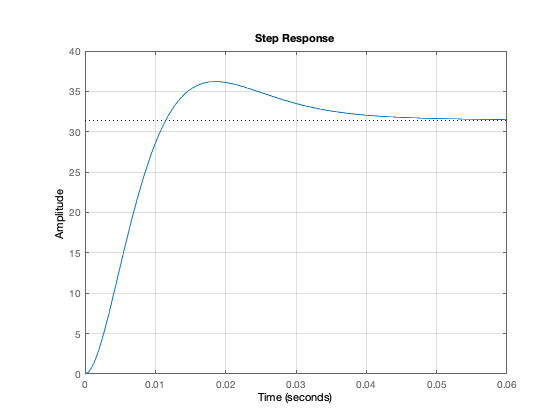

%  closed-loop tf
sysT1 = feedback(sysL1, 1);

%  closed-loop step response
figure;
step( sysT1 * wm_ref_rads );
grid on;


%    get step response params
stepinfo( sysT1* wm_ref_rads )

ans = struct with fields:
        RiseTime: 0.0078
    SettlingTime: 0.0400
     SettlingMin: 29.2683
     SettlingMax: 36.2057
       Overshoot: 15.2462
      Undershoot: 0
            Peak: 36.2057
        PeakTime: 0.0187


Con il nuovo guadagno $k'$, il tempo di salita è pari a  $t_r = 7.8\,\mathrm{ms}$.